clear;
close all;
clc;
initime = clock;
% func_path = fullfile('..', 'funcs');
addpath('../funcs');
% addpath(func_path);

Delta_e = 0.2;
Delta_i = 0.02;
Iattn = 0.02;
allTime = 4000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, allTime);
r = r*1000;
PET = getPET(v,g);

## firing rates by layers, E/I, 5 conds

env = getEnvelope(r);

bf_from = 50001;
bf_to = 100000;
af_from = 100001;
af_inr = 100000; % interval to show
af_to = af_from + af_inr;

ax_bf = bf_from - 1;
ax_af_1 = bf_from;
ax_af_2 = bf_from + 1*bf_to;
ax_af_3 = bf_from + 2*bf_to;
ax_af_4 = bf_from + 3*bf_to;
ax_af_5 = bf_from + 4*bf_to;

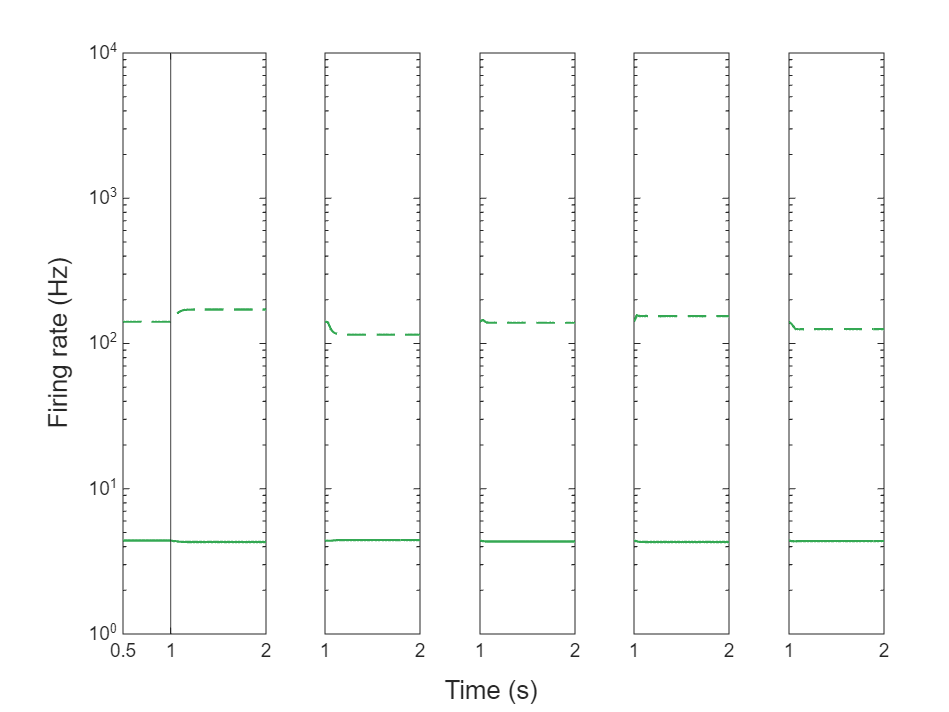

fig = figure();
commonWidth = 0.1;
timeax1 = 0:0.01:((bf_from-1)+af_inr)/100;
timeaxn = 0:0.01:af_inr/100;
colors = ["#EA4335", "#FBBC05", "#4285F4", "#34A853"];
% plot L2/3 in red #EA4335
% plot before stimulation
for layer = 1:4 % 1:L2/3, 2:L4, 3:L5, 4:L/6
    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    subplot(1,5,1);

    pos = get(gca, 'Position');
    pos(3) = 1.5 * commonWidth; % Modify the width
    set(gca, 'Position', pos);
    
    E_1 = plot(timeax1, env(pop_E,bf_from:bf_to+af_inr+1,1),'Color',colors(layer), 'LineWidth',1);
    hold on;
    I_1 = plot(timeax1, env(pop_I,bf_from:bf_to+af_inr+1,1),"--",'Color',colors(layer), 'LineWidth',1);
    set(gca, 'YScale', 'log');
    xline(500);
    xticks([0 500 1500]);
    xticklabels([0.5 1 2]);
    ylim([1 10000]);
    
    for cond = 2:5
    subplot(1,5,cond);

    pos = get(gca, 'Position');
    pos(1) = pos(1) + (1.5 - 1) * commonWidth; % Shift the subplot to right
    pos(3) = commonWidth; % Modify the width
    set(gca, 'Position', pos);

    E_n = plot(timeaxn, env(pop_E,af_from:af_to,cond),'Color',colors(layer), 'LineWidth',1);
    hold on;
    I_n = plot(timeaxn, env(pop_I,af_from:af_to,cond),"--",'Color',colors(layer), 'LineWidth',1);
    set(gca, 'YScale', 'log');
    set(gca,'yticklabel',[])
    xticks([0 1000]);
    xticklabels([1 2]);
    ylim([1 10000]);
    end
end

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Firing rate (Hz)');
xlabel(han,'Time (s)');

figure();    
pop_E = 7;
pop_I = 8;
    subplot(1,5,1);
    E_1 = plot(timeax1, env(pop_E,bf_from:bf_to+af_inr+1,1),'Color',colors(layer), 'LineWidth',1);
    hold on;
    I_1 = plot(timeax1, env(pop_I,bf_from:bf_to+af_inr+1,1),"--",'Color',colors(layer), 'LineWidth',1);
    set(gca, 'YScale', 'log');
    xline(500);
    xticks([0 500 1500]);
    xticklabels([0.5 1 2]);
    ylim([1 10000]);
    
    for cond = 2:5
    subplot(1,5,cond);
    E_n = plot(timeaxn, env(pop_E,af_from:af_to,cond),'Color',colors(layer), 'LineWidth',1);
    hold on;
    I_n = plot(timeaxn, env(pop_I,af_from:af_to,cond),"--",'Color',colors(layer), 'LineWidth',1);
    set(gca, 'YScale', 'log');
    set(gca,'yticklabel',[])
    xticks([0 1000]);
    xticklabels([1 2]);
    ylim([1 10000]);
    end

## firing rates by layers, E +/- I, 5 cons